# DAAP HW1

*Alberto Doimo*

*Paolo Ostan *

## **Talking Instrument creation **

### **Parameters initialization**

clc; close all; clear all;

instr_name = "piano.wav";
speech_name = "speech.wav";
talking_instr_res_name = "talking_instr_res.wav";

### 01) First test with verbose parameters to check functioning of the script

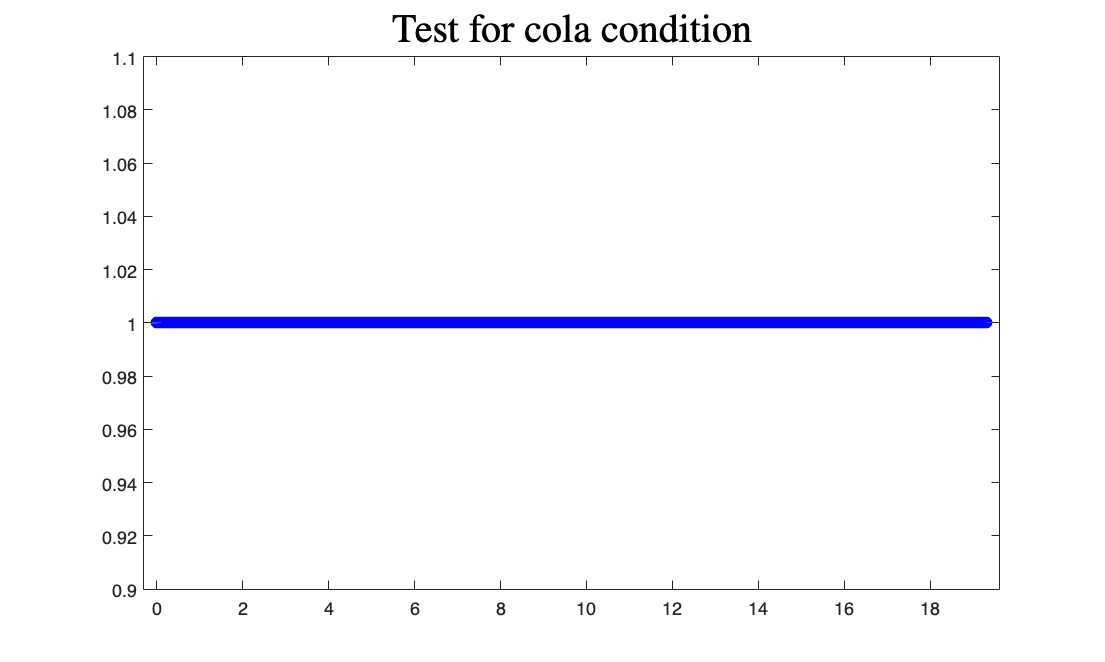

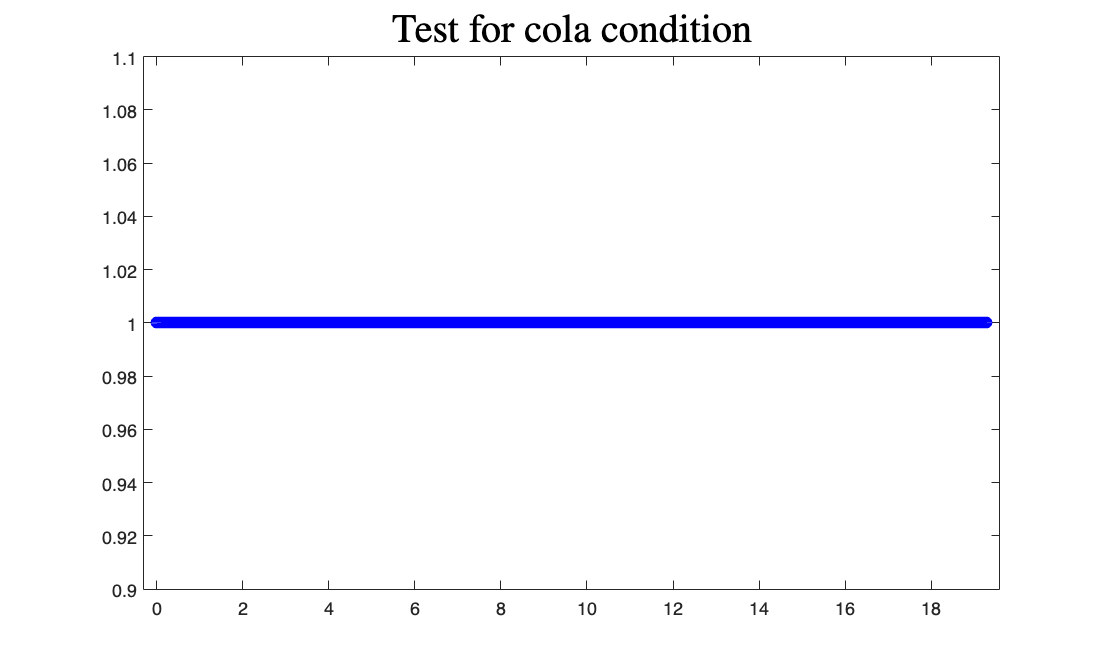

Precision check plots for piano signal


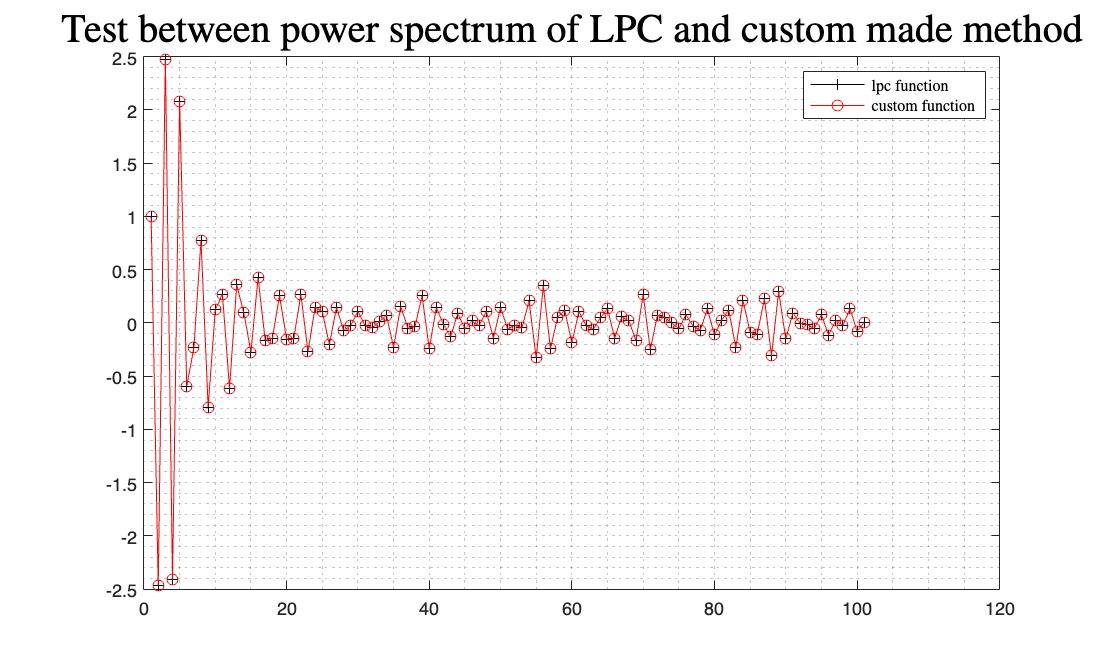

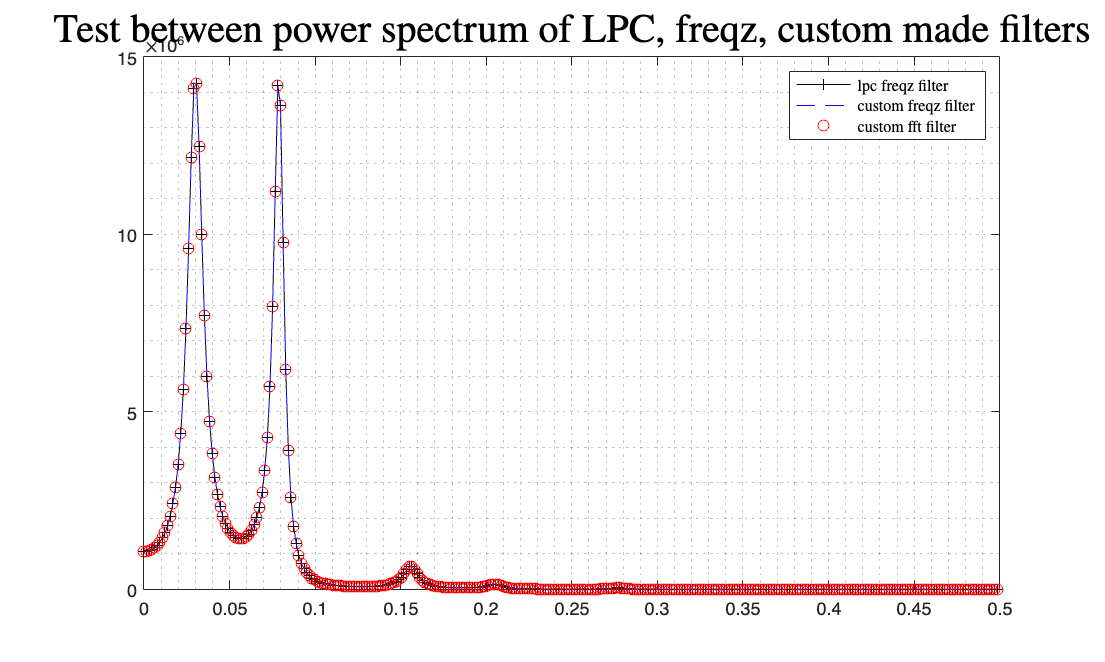

Precision check plots for speech signal


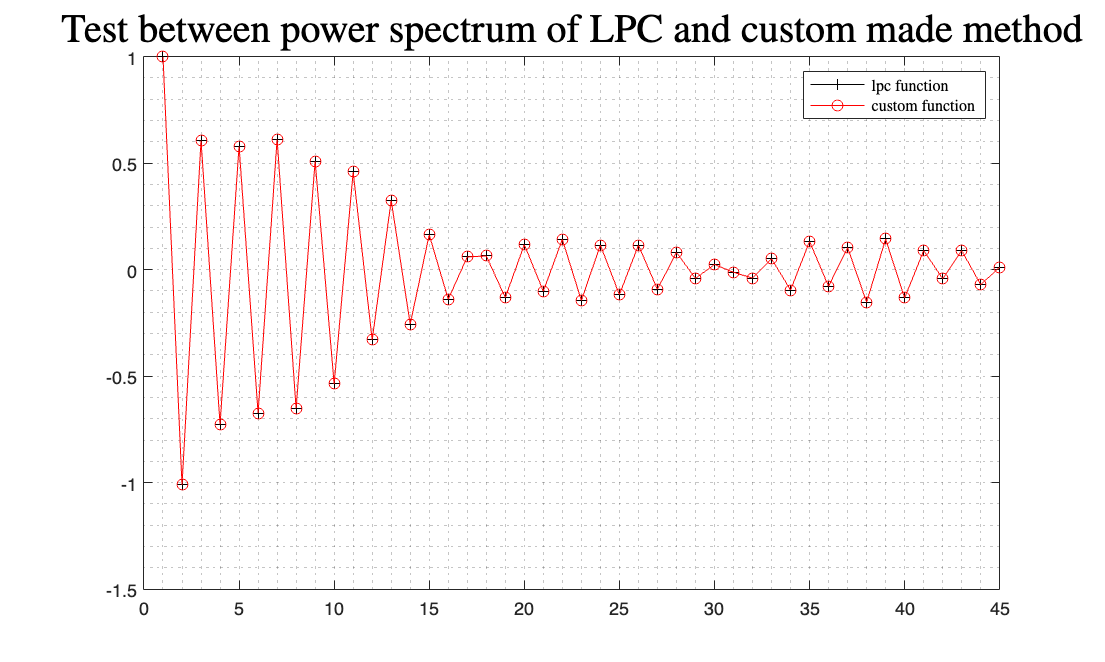

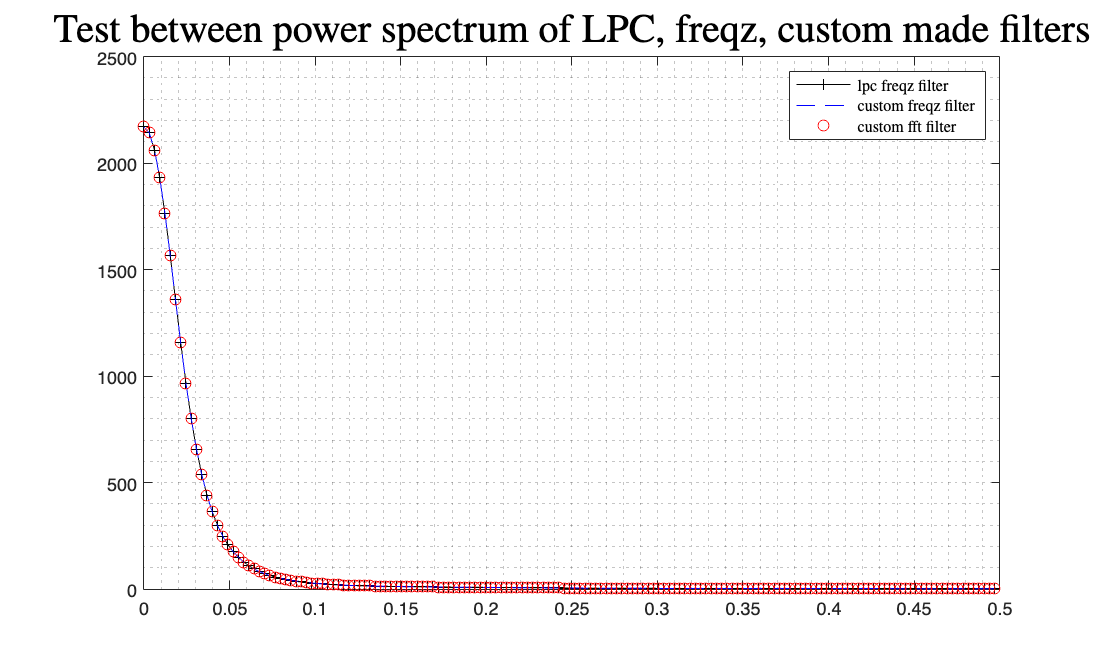

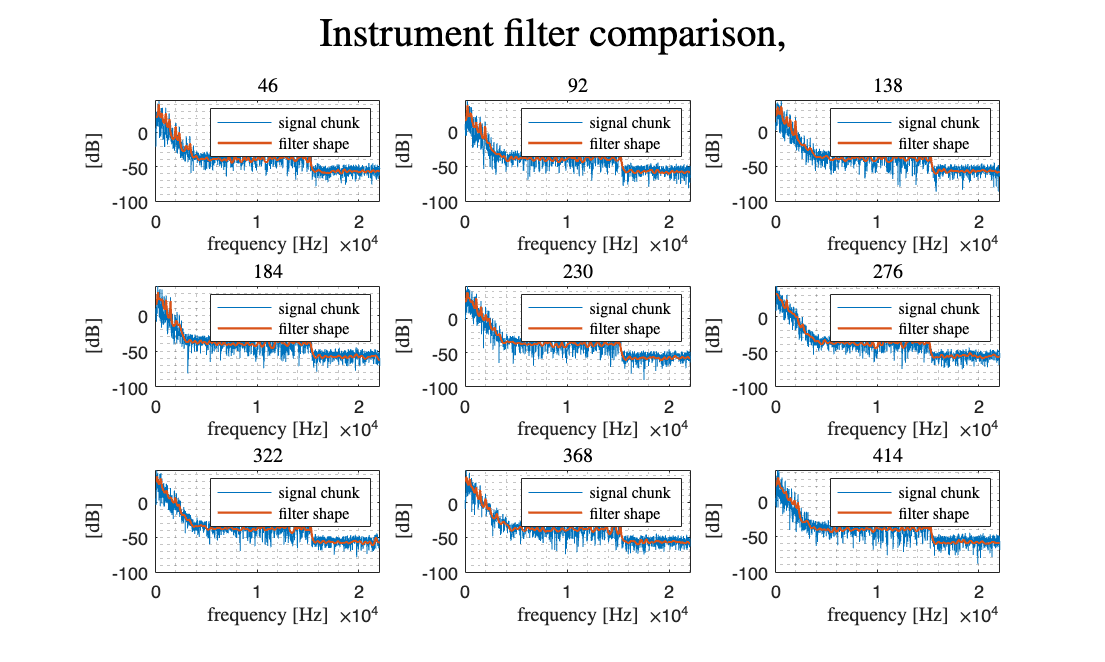

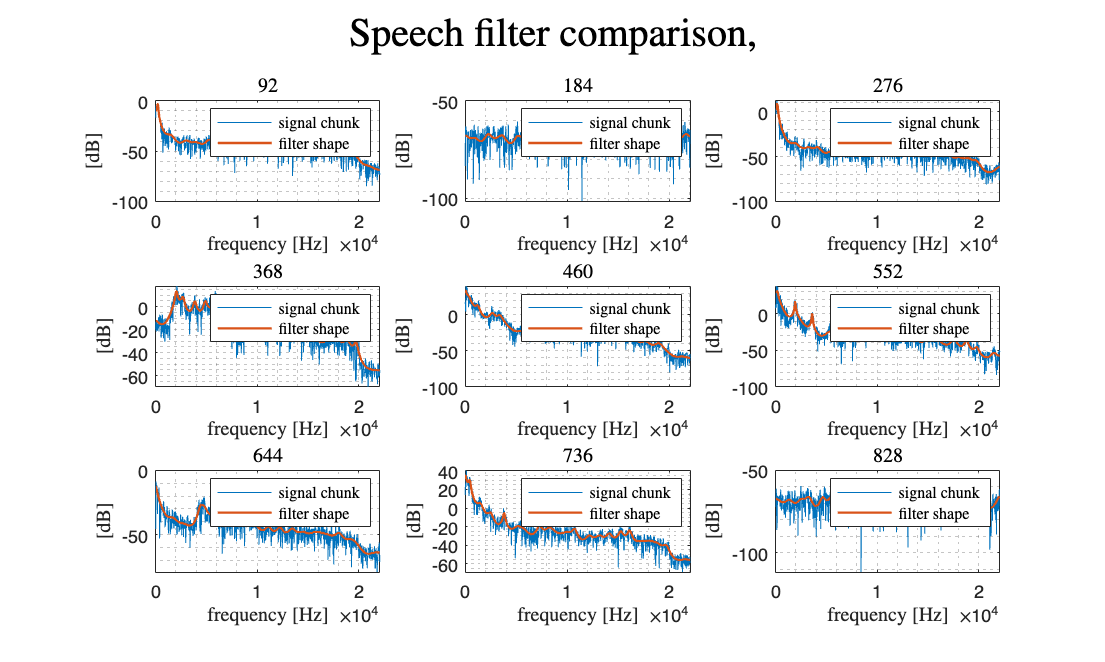

close all;

tic
talking_instr_res_name = "010_talking_instr_verb1.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,4096,44,100,"linSolve",0.3,10^-1,100000,"zeros",0,0,1,"","mean");

toc

Elapsed time is 3.718467 seconds.


## 02) test for various threshold values using steepest descent

close all;clc;
disp("threshold 10^-1")

threshold 10^-1


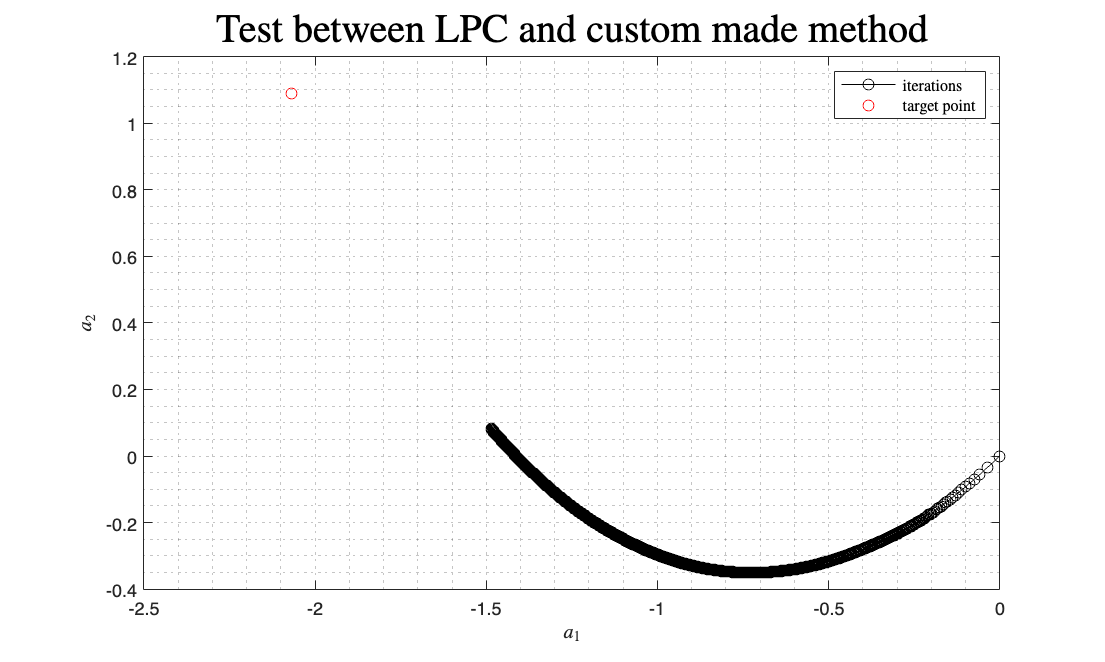

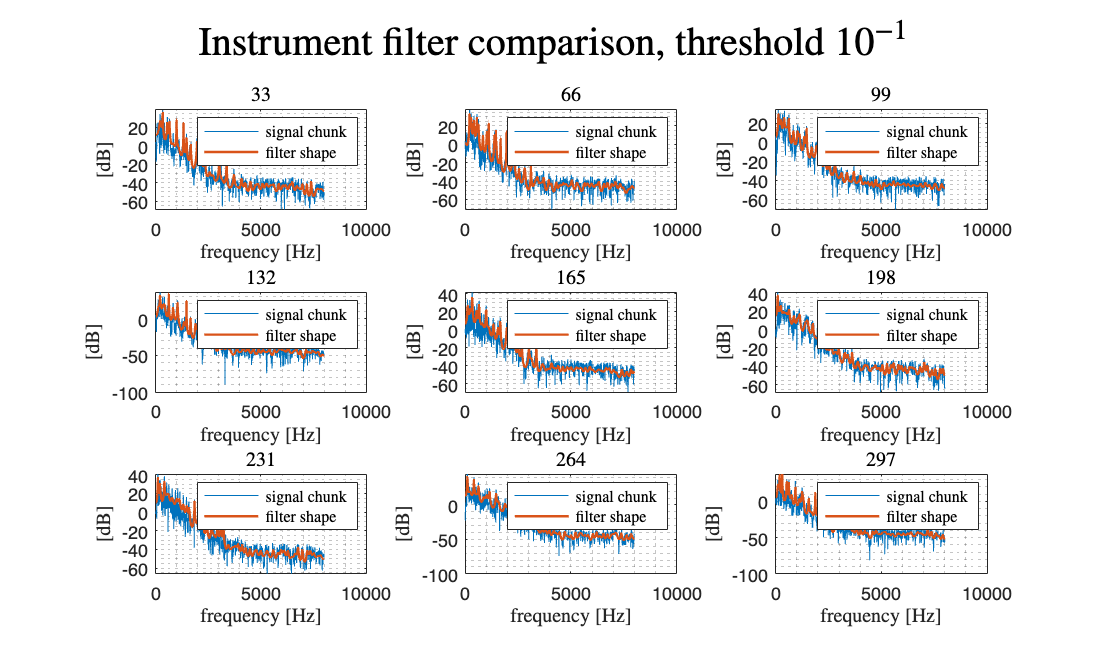

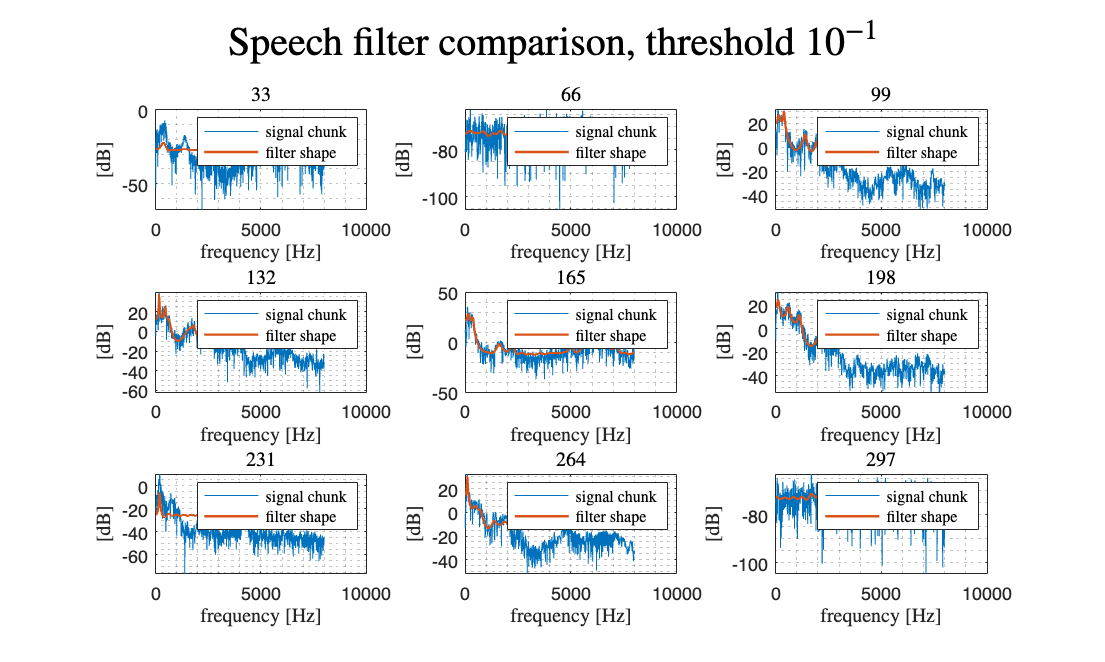

tic
talking_instr_res_name = "020_talking_instr_10_1.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-1,100000,"zeros",1,0,0,"threshold $10^{-1}$","mean");


toc

Elapsed time is 7.673943 seconds.


disp("threshold 10^-2")

threshold 10^-2


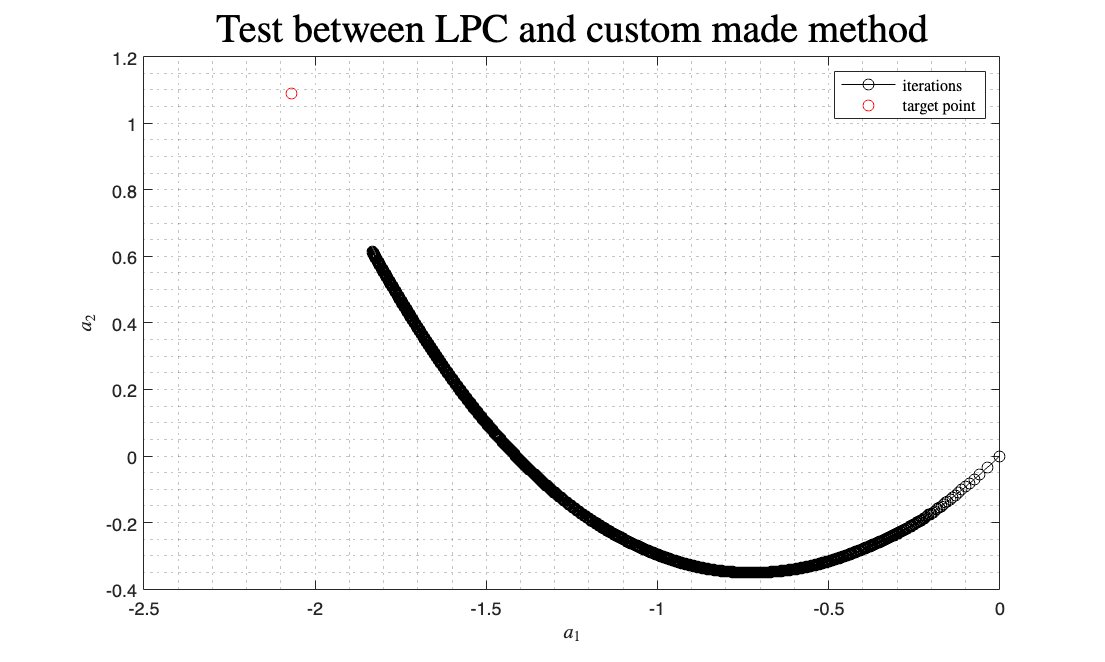

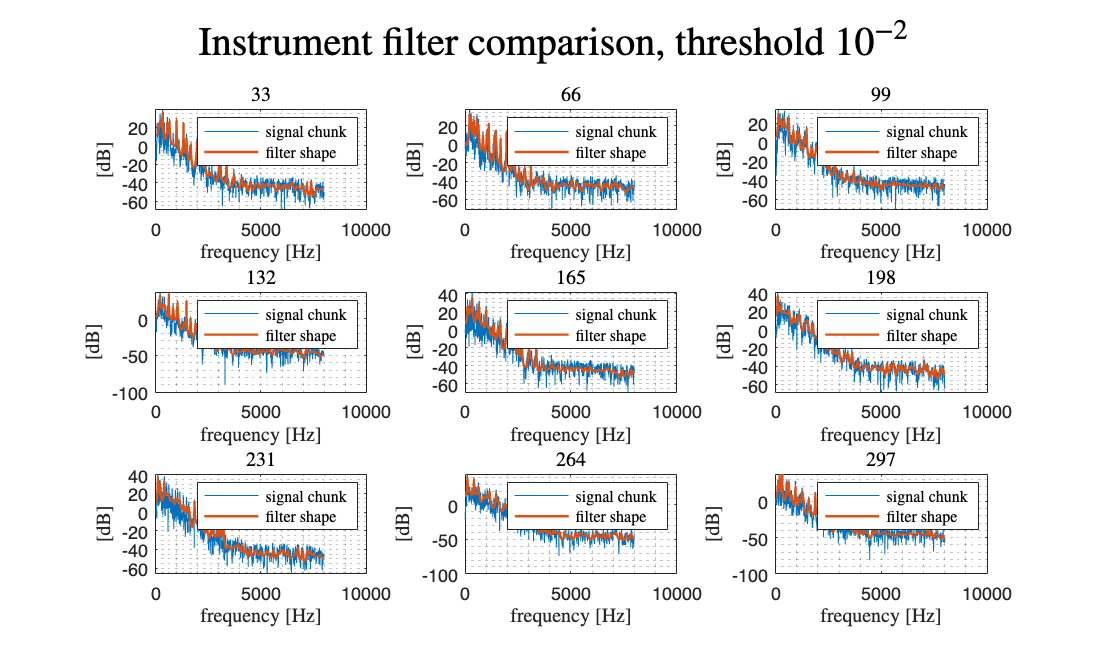

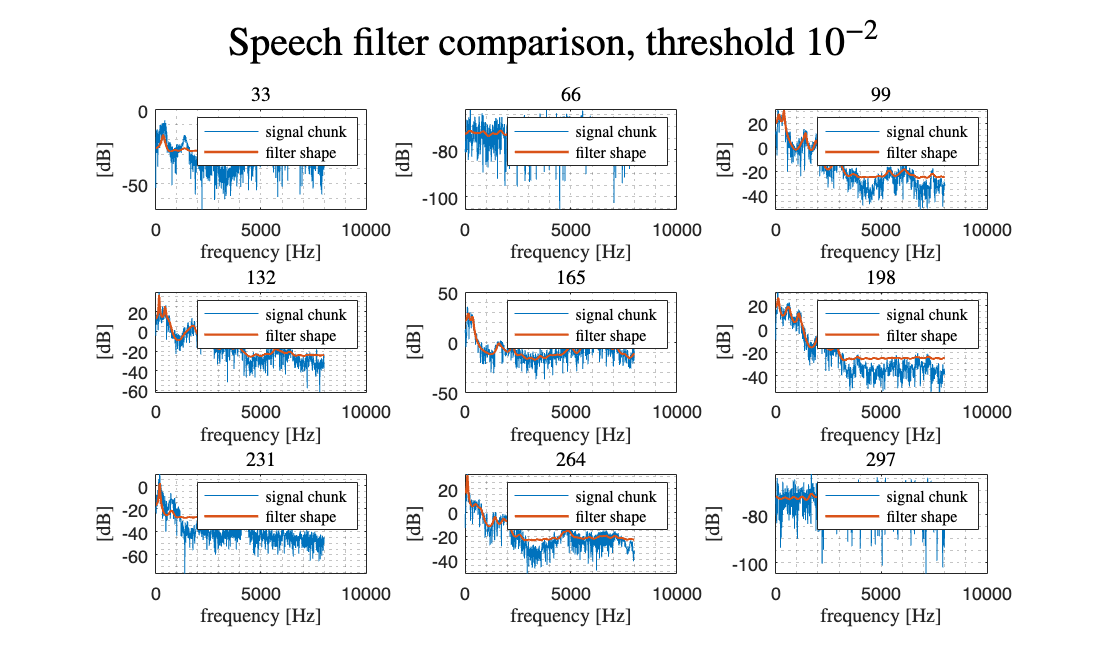

tic
talking_instr_res_name = "021_talking_instr_10_2.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-2,100000,"zeros",1,0,0,"threshold $10^{-2}$","mean");

toc

Elapsed time is 39.096547 seconds.


disp("threshold 10^-4")

threshold 10^-4


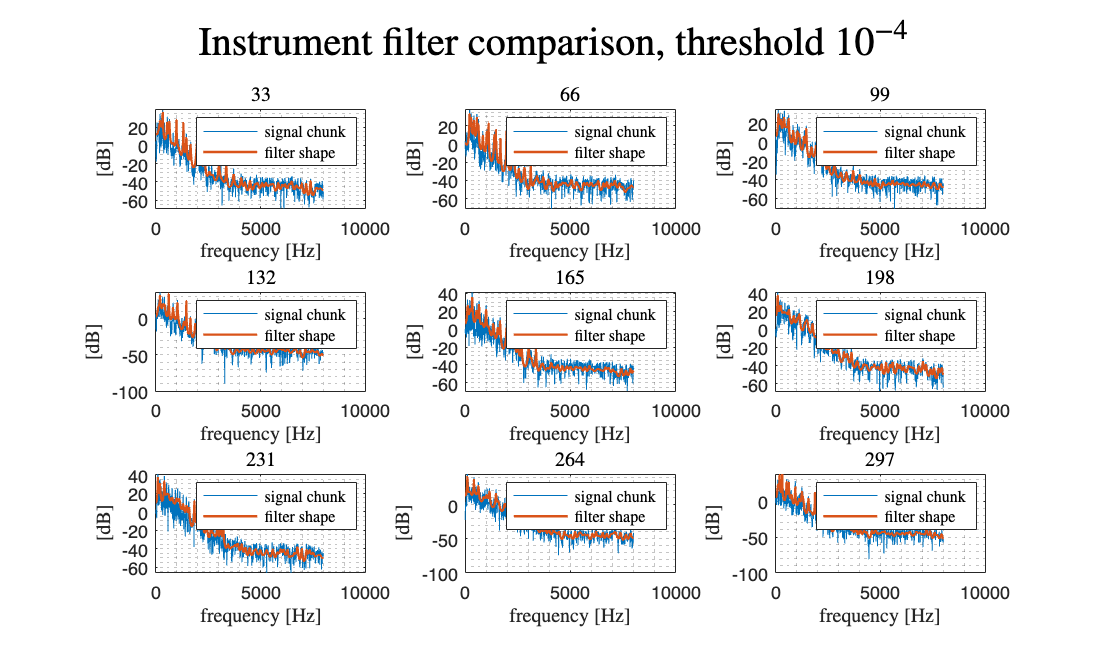

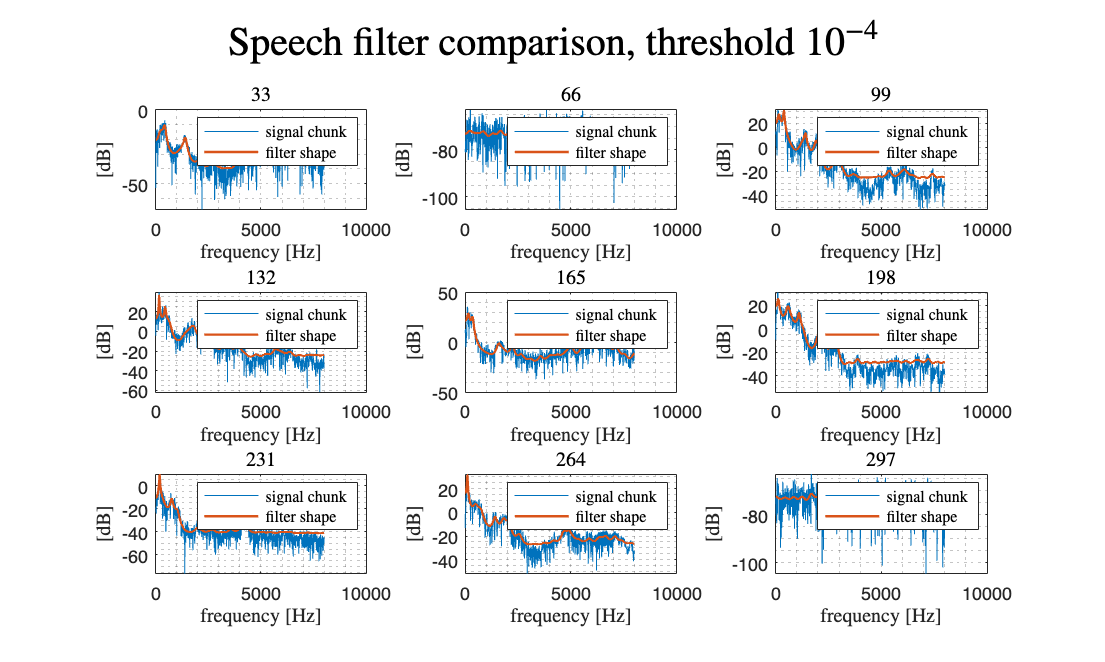


tic
talking_instr_res_name = "022_talking_instr_10_4.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-4,100000,"zeros",1,0,0,"threshold $10^{-4}$","mean");

toc

Elapsed time is 56.015590 seconds.


## 03) test for various coefficients initialization values using steepest descent

disp("time for speech steepest descent equals to previous value")

time for speech steepest descent equals to previous value


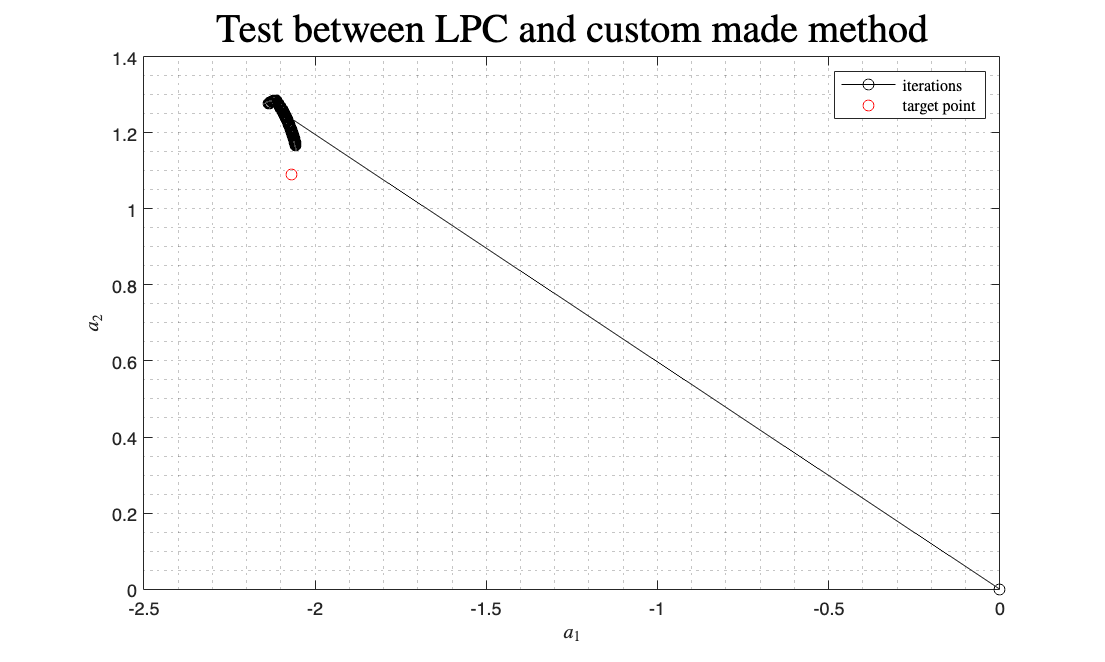

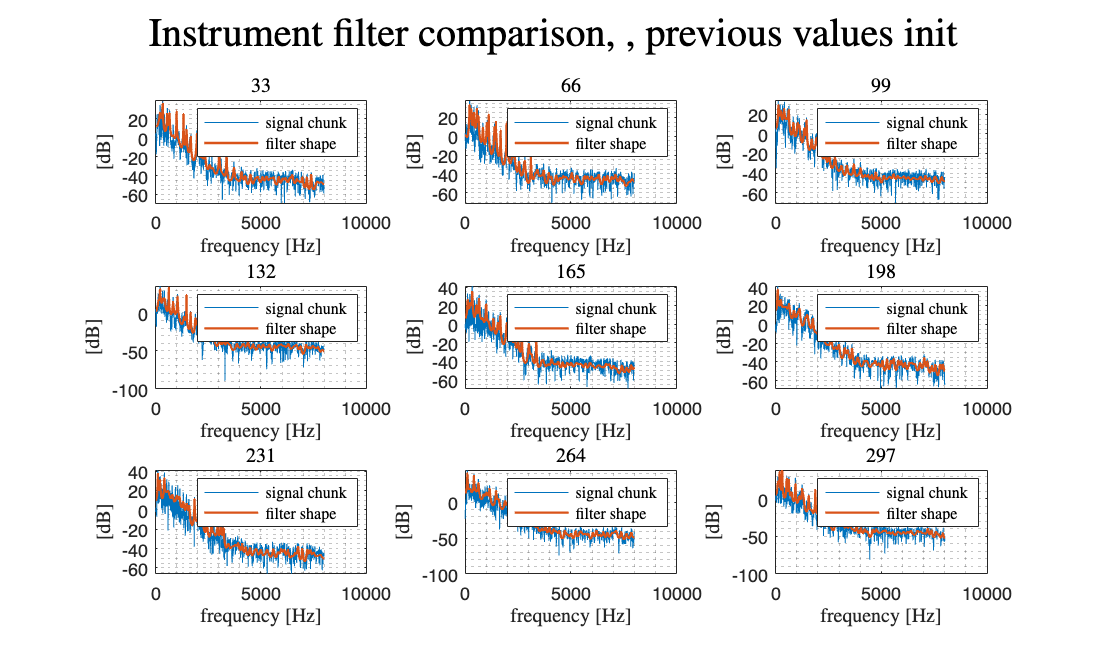

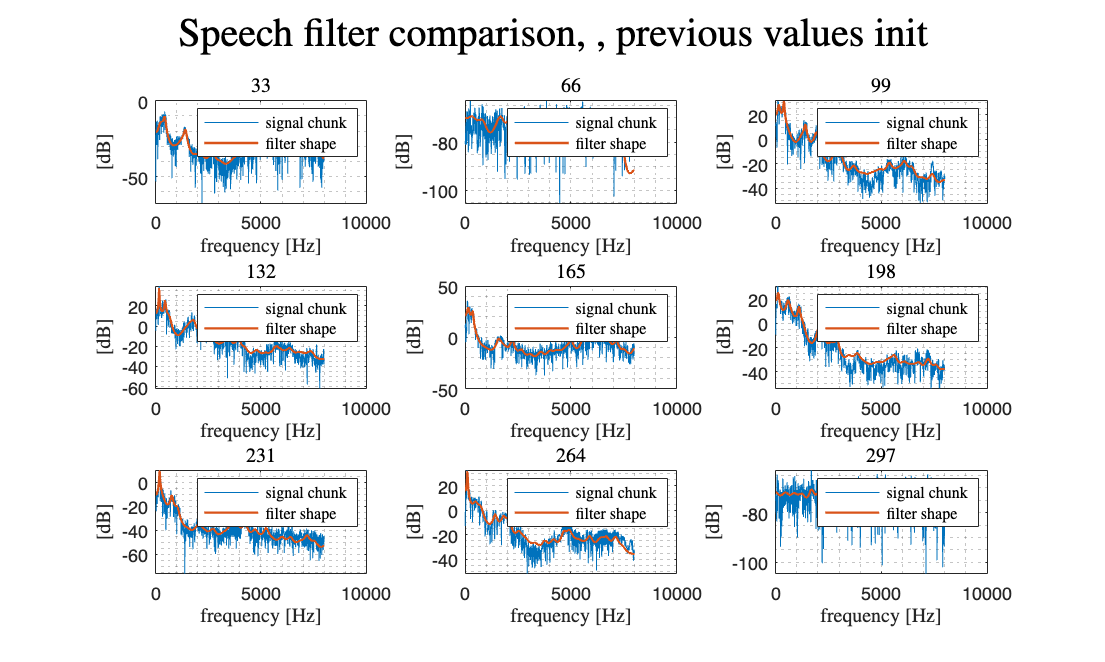


tic
talking_instr_res_name = "030_talking_instr_zeros.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-4,100000,"prev",1,0,0,", previous values init","mean");

toc

Elapsed time is 55.234375 seconds.


disp("time for speech steepest descent equals to zero")

time for speech steepest descent equals to zero


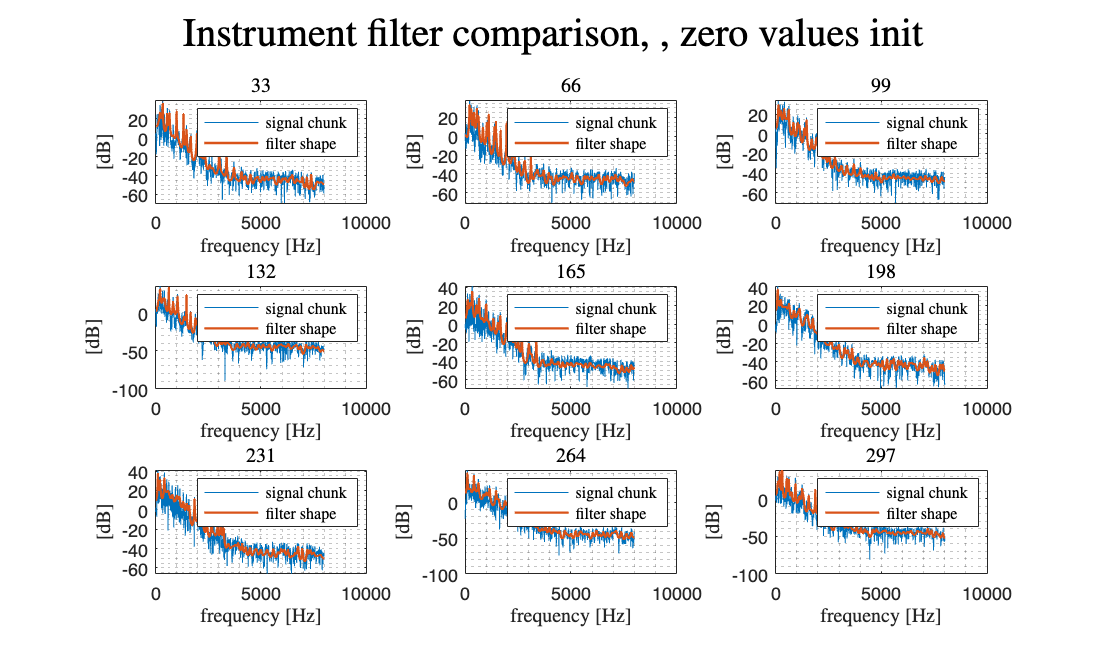

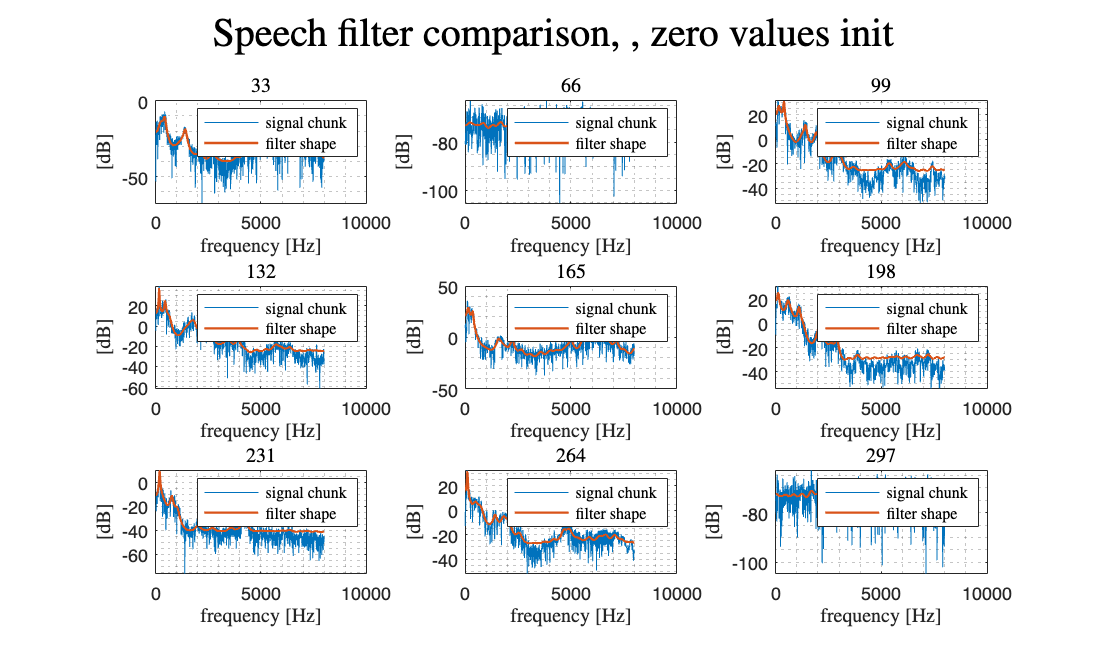



tic
talking_instr_res_name = "031_talking_instr_zeros.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-4,100000,"zeros",1,0,0,", zero values init","mean");

toc

Elapsed time is 54.799807 seconds.



disp("time for speech steepest descent equals to one")

time for speech steepest descent equals to one


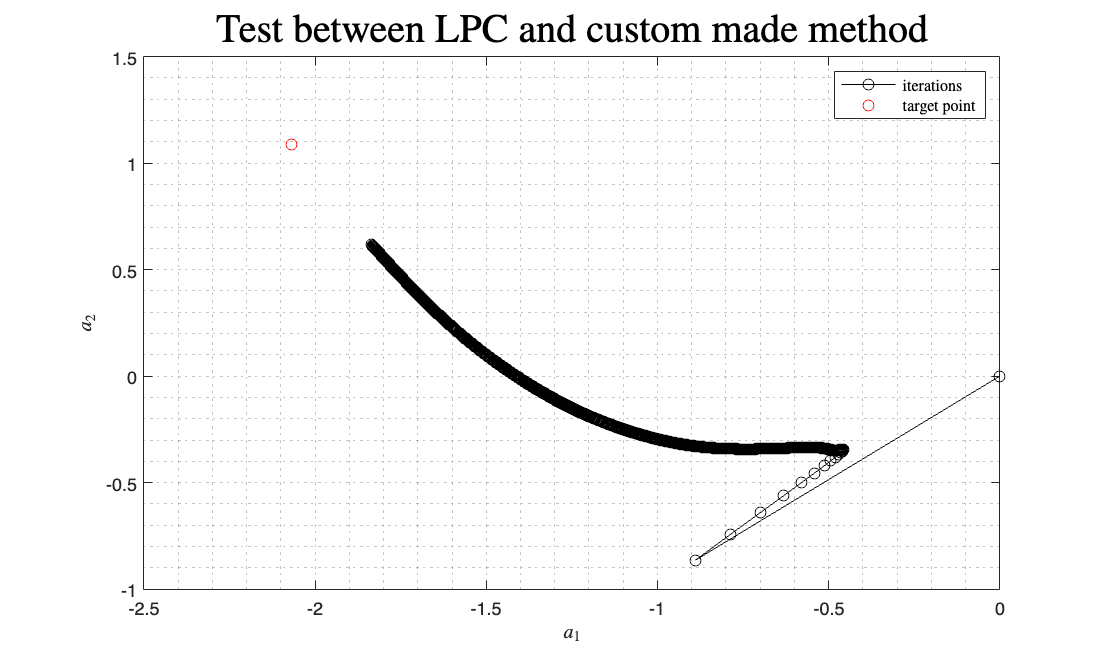

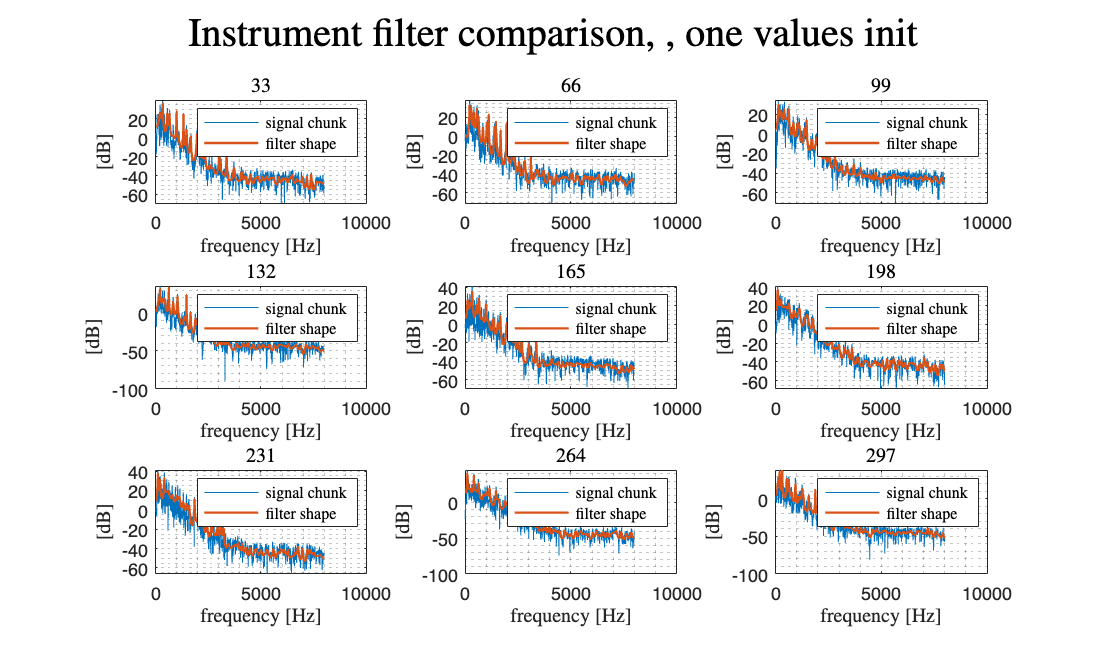

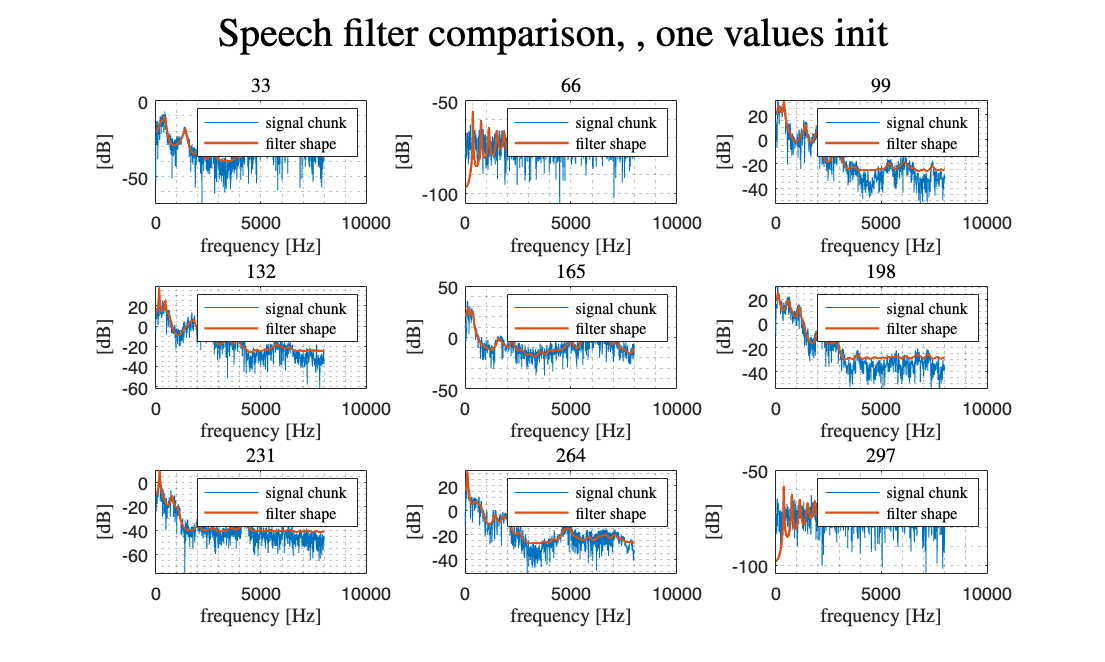


tic
talking_instr_res_name = "032_talking_instr_ones.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-4,100000,"ones",1,0,0,", one values init","mean");

toc

Elapsed time is 55.121778 seconds.



disp("time for speech steepest descent equals to random values")

time for speech steepest descent equals to random values


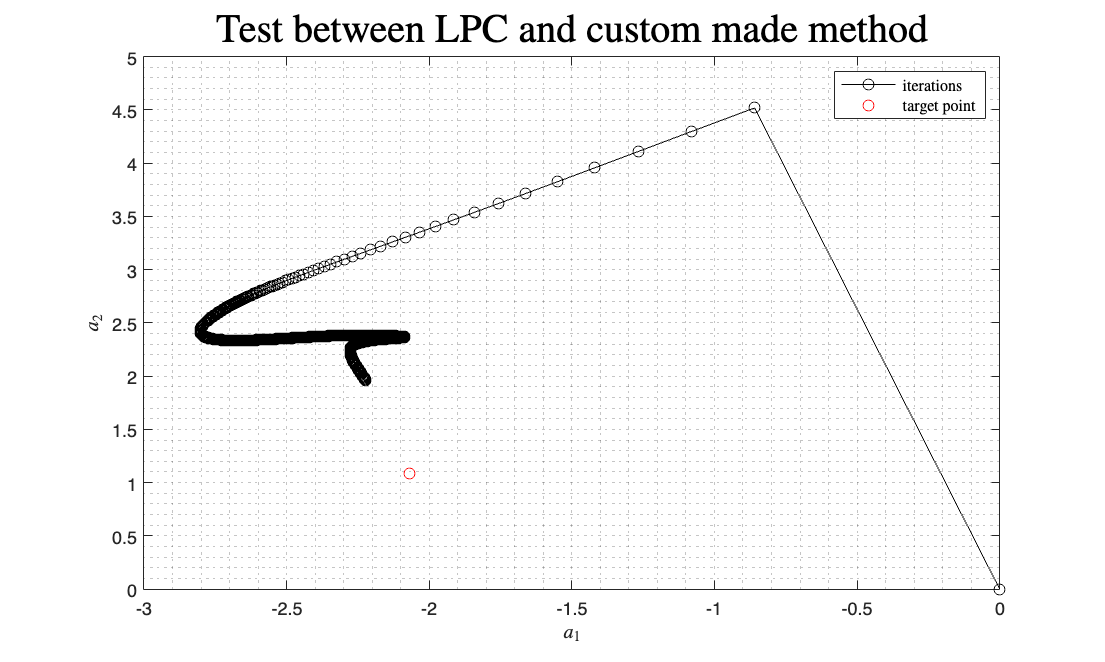

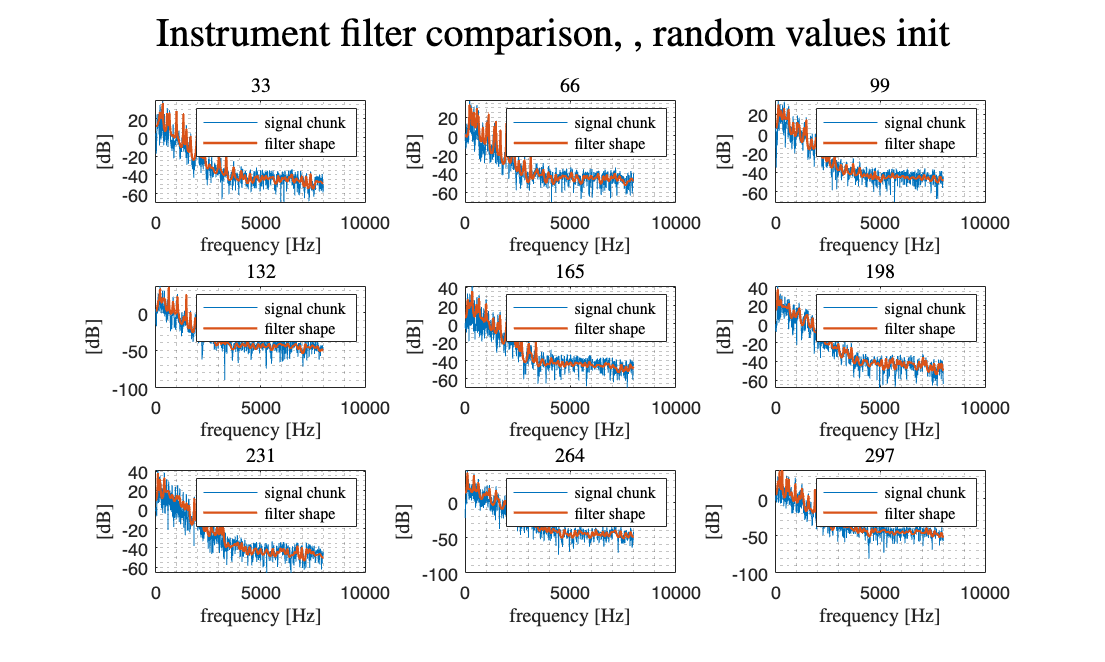

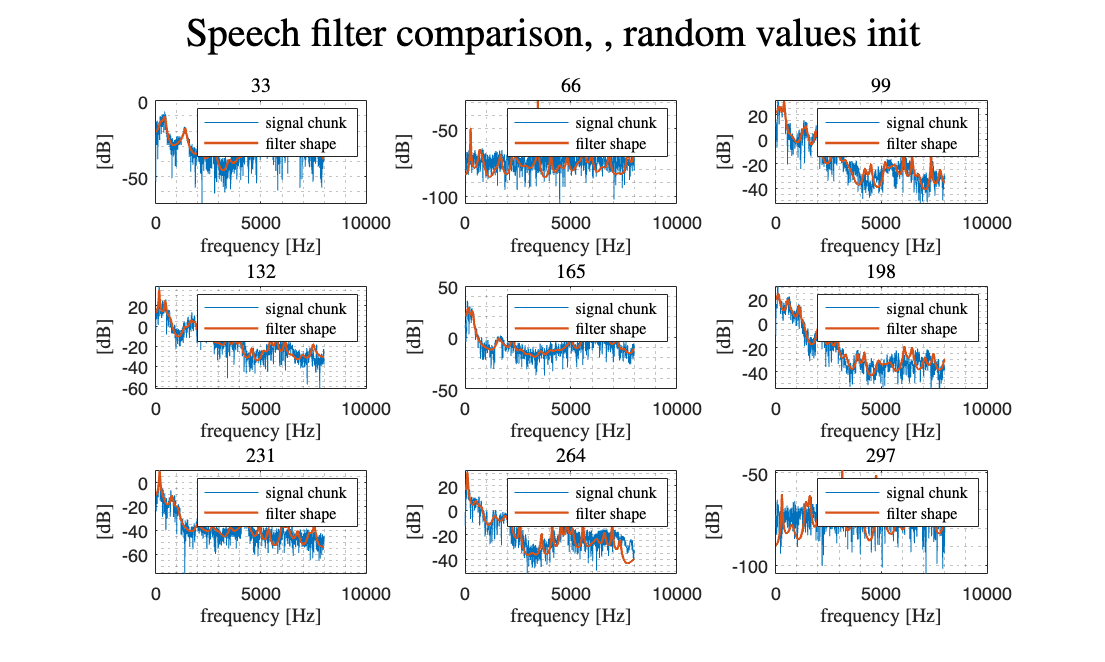


tic
talking_instr_res_name = "033_talking_instr_randn.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-4,100000,"randn",1,0,0,", random values init","mean");

toc

Elapsed time is 56.501991 seconds.


## 04) Test for various window lengths

disp("time and audio output for speech closed form solver different window lengths")

time and audio output for speech closed form solver different window lengths


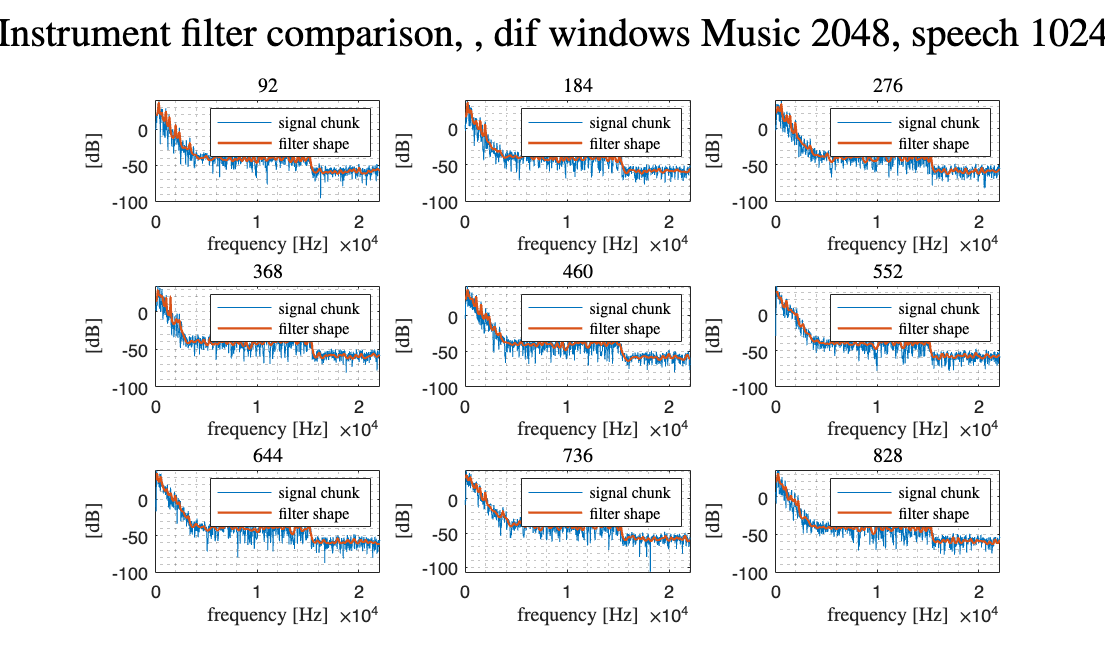

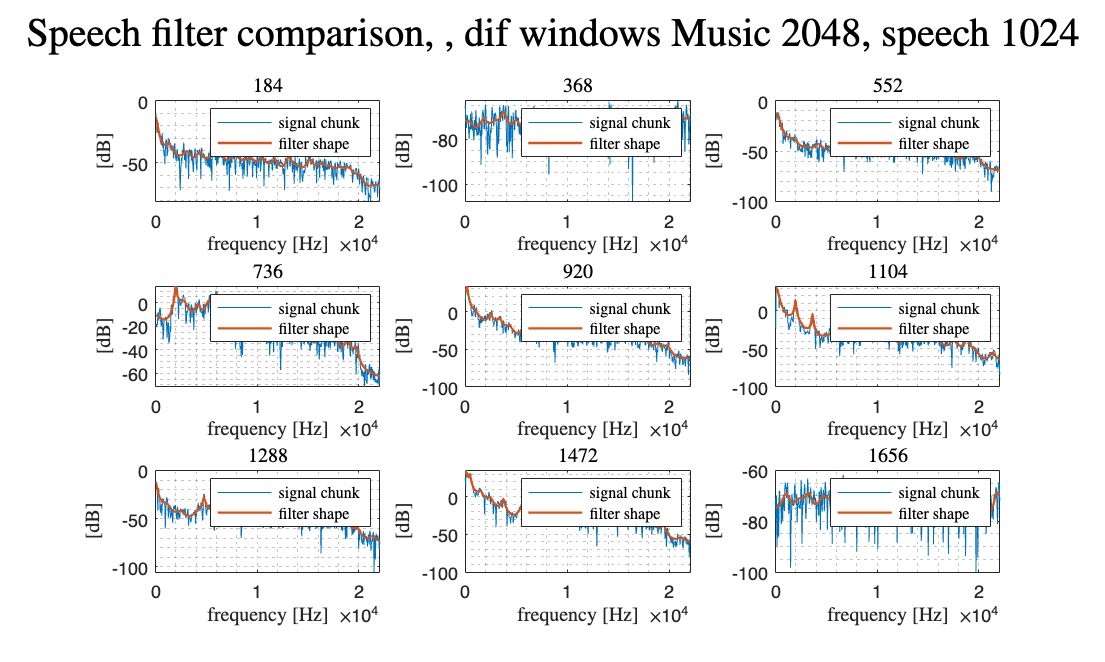


tic
talking_instr_res_name = "040_talking_instr_S1024_M2048.wav";
main(instr_name, speech_name, talking_instr_res_name,1024,2048,44,100,"linSolve",0.3,10^-4,100000,"randn",0,0,0,", dif windows Music 2048, speech 1024","mean");

toc

Elapsed time is 2.039760 seconds.


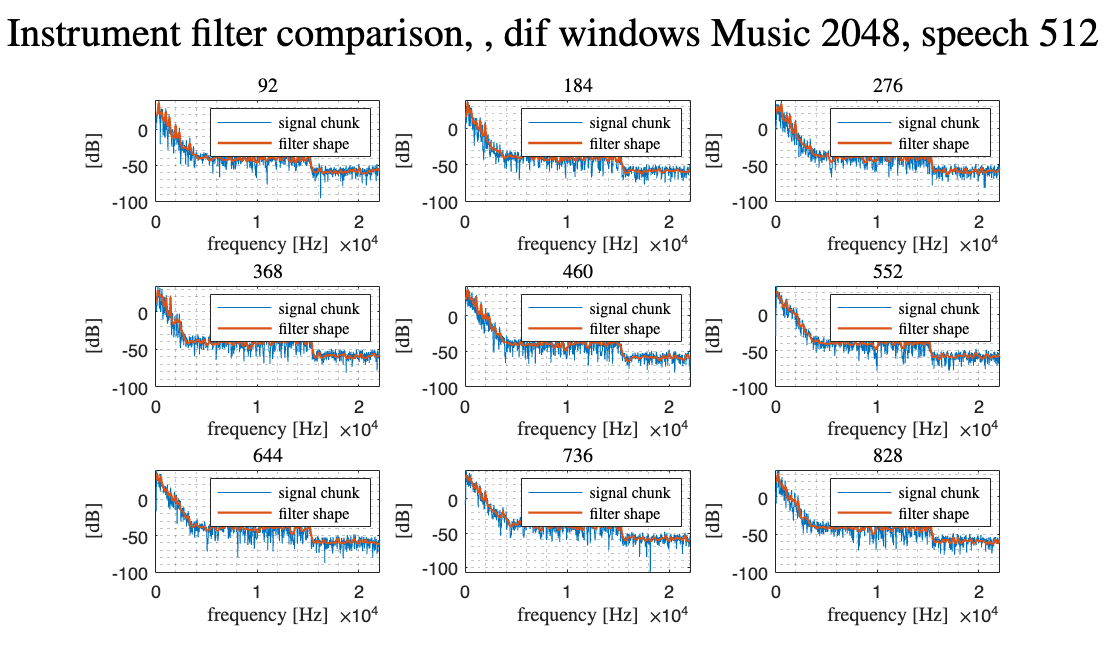

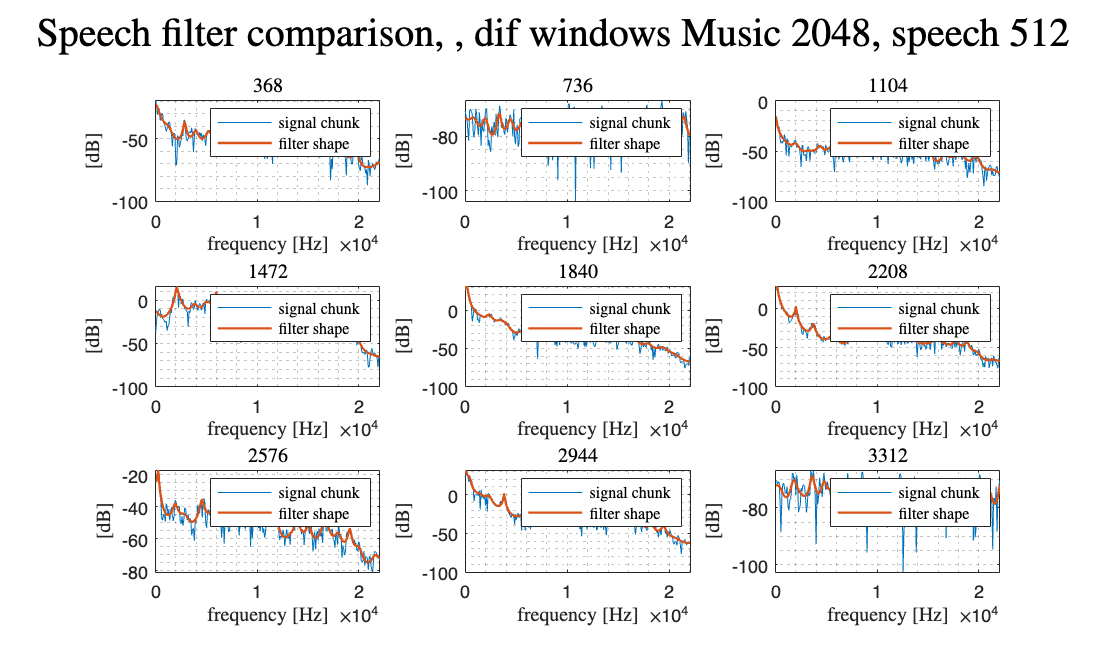


tic
talking_instr_res_name = "040_talking_instr_S512_M2048.wav";
main(instr_name, speech_name, talking_instr_res_name,512,2048,44,100,"linSolve",0.3,10^-4,100000,"randn",0,0,0,", dif windows Music 2048, speech 512","mean");

toc

Elapsed time is 2.033631 seconds.


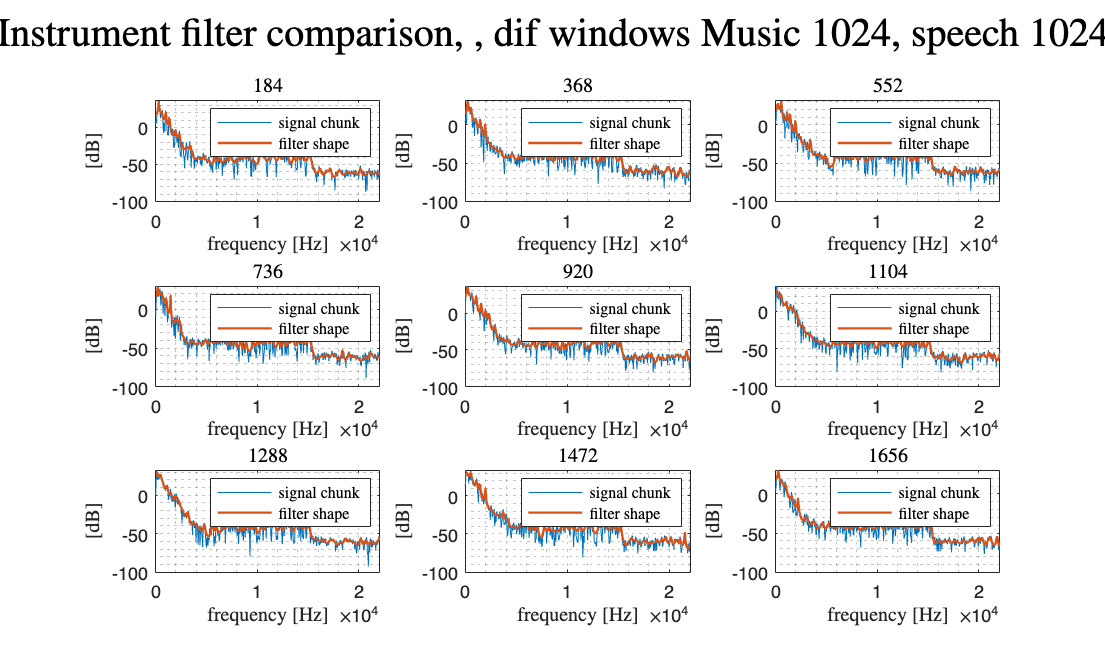

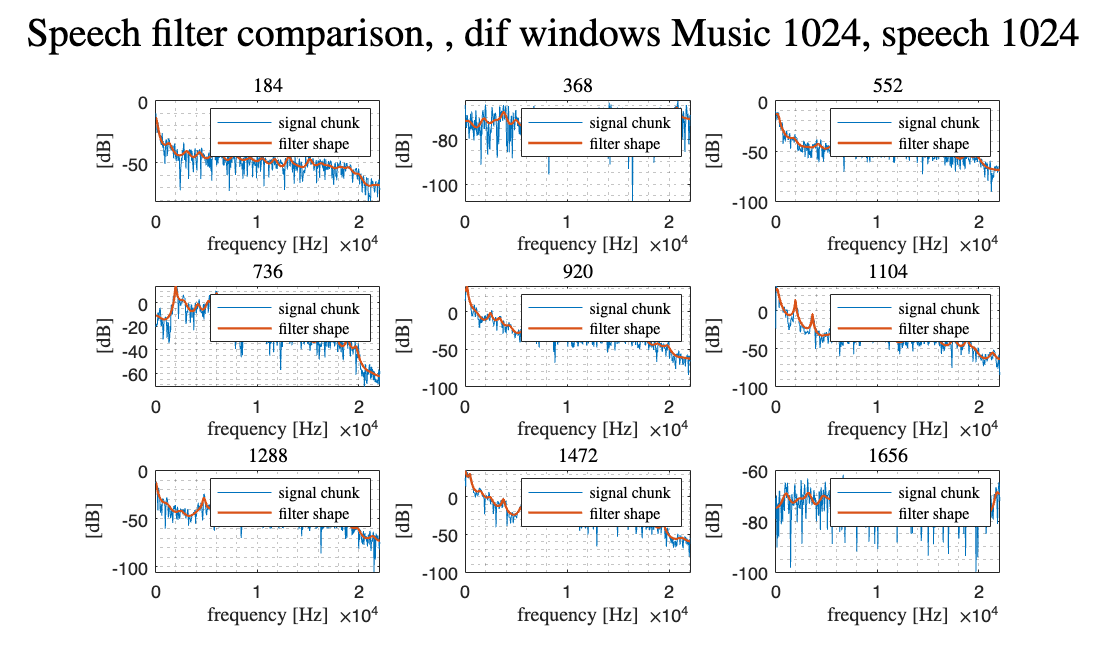


tic
talking_instr_res_name = "040_talking_instr_S1024_M1024.wav";
main(instr_name, speech_name, talking_instr_res_name,1024,1024,44,100,"linSolve",0.3,10^-4,100000,"randn",0,0,0,", dif windows Music 1024, speech 1024","mean");

toc

Elapsed time is 2.135256 seconds.


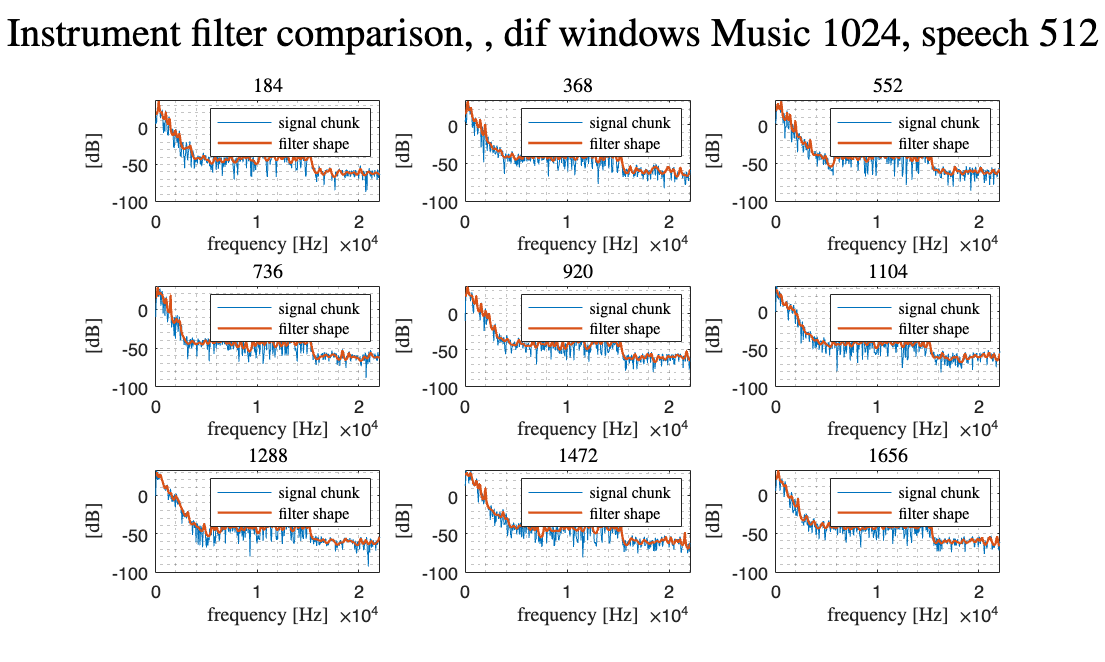

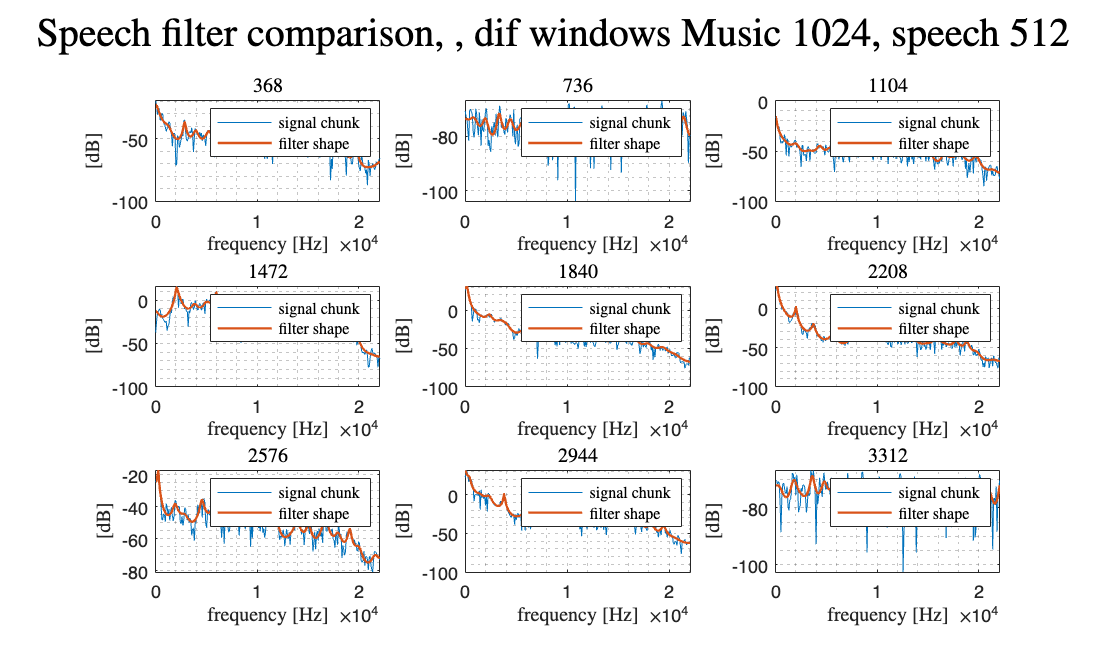


tic
talking_instr_res_name = "040_talking_instr_S512_M1024.wav";
main(instr_name, speech_name, talking_instr_res_name,512,1024,44,100,"linSolve",0.3,10^-4,100000,"randn",0,0,0,", dif windows Music 1024, speech 512","mean");

toc

Elapsed time is 2.179547 seconds.
